% Oppgave som ber deg se på en sprangrespons, og hvordan finne Transferfunksjonen fra det
% Script for å beregne dempingsfaktor (zeta) og transferfunksjon for et system
% Basert på prosent oversving (OS), tid til maksimum oversving (Tp), og sluttverdi (K)

% 1. Sett inn verdier her:
OS = 0.344;       % Prosent oversving (skriv inn som desimaltall, f.eks. 0.1 for 10%)
Tp = 0.0276;      % Tid til maksimum oversving (sekund)
K = 2.85;        % Sluttverdi på systemets respons (forsterkning, stasjonærverdi)

% 2. Beregn dempingsfaktor (zeta) basert på prosent oversving
% Ligningen for OS = e^(-zeta * pi / sqrt(1 - zeta^2))
f = @(zeta) exp(-zeta * pi / sqrt(1 - zeta^2)) - OS;

% Startgjett for zeta
initial_guess = 0.5;

% Finn zeta ved å løse ligningen
zeta = fsolve(f, initial_guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



% Vis resultatet for dempingsfaktoren
fprintf('Dempingsfaktor (zeta) beregnet: %.3f\n', zeta);

Dempingsfaktor (zeta) beregnet: 0.322



% 3. Beregn naturlig frekvens (omega_n) basert på Tp og zeta
omega_n = pi / (Tp * sqrt(1 - zeta^2));

% Vis resultatet for naturlig frekvens
fprintf('Naturlig frekvens (omega_n) beregnet: %.3f rad/s\n', omega_n);

Naturlig frekvens (omega_n) beregnet: 120.213 rad/s



% 4. Opprett transferfunksjonen G(s) basert på zeta, omega_n og K
numerator = K * omega_n^2;
denominator = [1, 2*zeta*omega_n, omega_n^2];
G = tf(numerator, denominator)

G =
 
          4.119e04
  ------------------------
  s^2 + 77.33 s + 1.445e04
 
Continuous-time transfer function.
Model Properties



% 5. Vis transferfunksjonen
fprintf('Transferfunksjon G(s):\n');

Transferfunksjon G(s):


disp(G);

  tf with properties:

       Numerator: {[0 0 4.1186e+04]}
     Denominator: {[1 77.3271 1.4451e+04]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



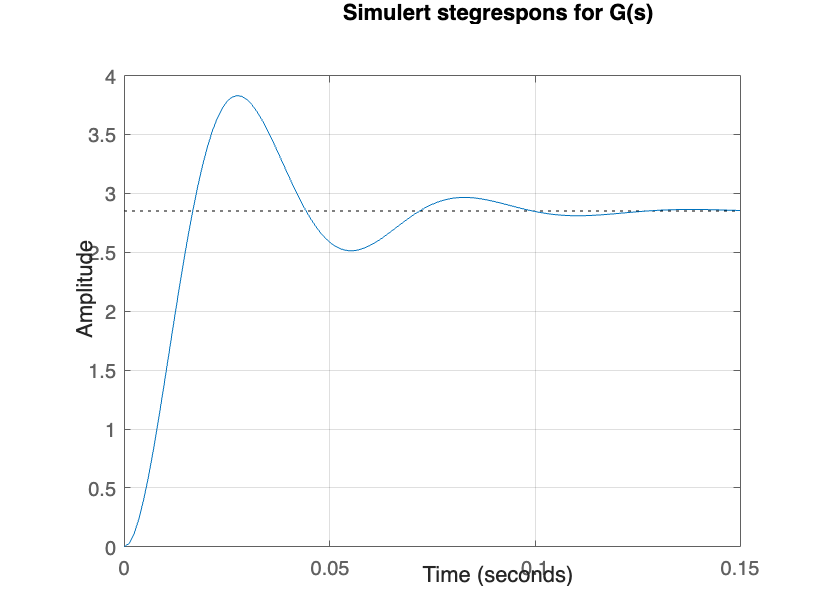


% 6. Plott stegresponsen for å verifisere
figure;
step(G);
title('Simulert stegrespons for G(s)');
grid on;


% End of script
